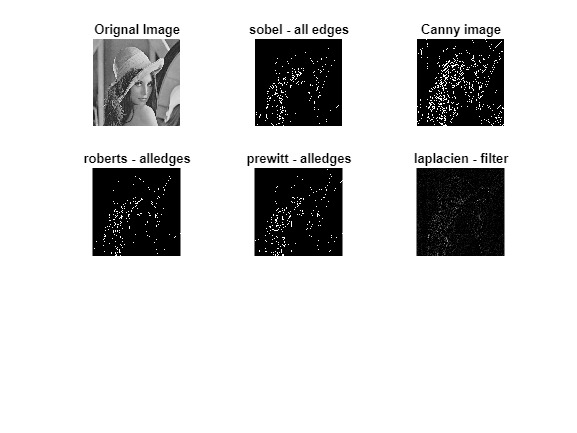

a = imread('lena_gray.jpeg');



subplot(3,3,1);
imshow(a);
title('Orignal Image');



sobelvr = edge(a,'sobel','both');
subplot(3,3,2);
imshow(sobelvr,[]);
title('sobel - all edges');



subplot(3,3,3);
cannyedg=edge(a,'canny');
imshow(cannyedg,[]);
title('Canny image');



robertsedg = edge(a, 'roberts');
subplot(3,3,4);
imshow(robertsedg , []);
title('roberts - alledges');



sedg = edge(a,'prewitt');
subplot(3,3,5);
imshow(sedg, []);
title('prewitt - alledges');



f = fspecial('laplacian');
lapedg = imfilter(a, f, 'symmetric');
subplot(3,3,6);
imshow(lapedg, []);
title('laplacien - filter');